# **Part 2: Configure Parameters required for Bird-Eye view**

In this step, we need to convert perspective view into bird's eye view for distance measurement.

Select region of interest in the given input image by selecting four points on the image.

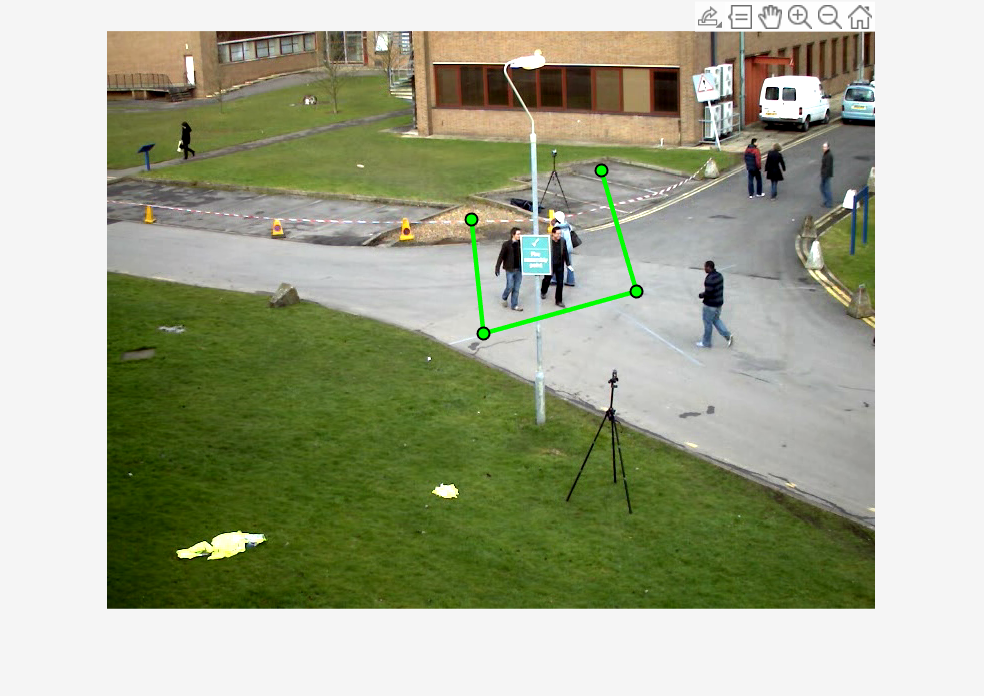

v = VideoReader('./sample.avi', "CurrentTime", 15);

%
I = readFrame(v);
% I = imresize(I,[300,300]);
imshow(I)

h = drawpolyline('Color','green');

Porig = h.Position;

Visualize the points selected in the perspective view.

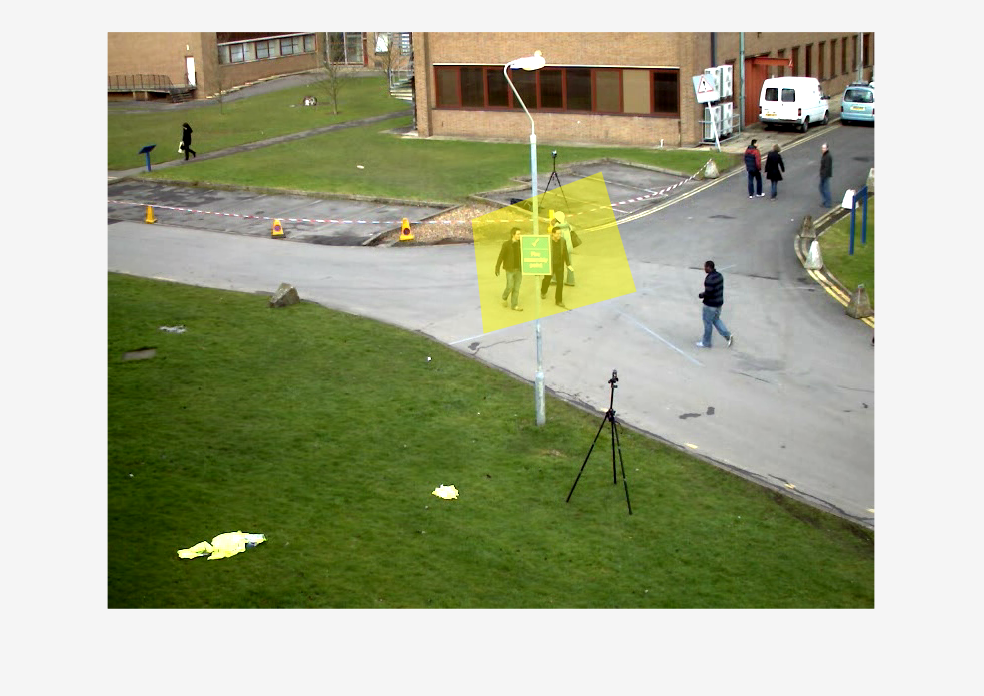

Psel = reshape(Porig', 1, []);
Ori = insertShape(I, 'FilledPolygon', Psel, 'LineWidth', 5, ...
    'Opacity', 0.5);
imshow(Ori)

Convert selected 4 points into rectangle points, get the transformation matrix and warp the image.

sz = size(I);
Ppost = [1 1; sz(1) 1; sz(1) sz(2); 1 sz(2)];
T = fitgeotrans(Porig, Ppost,'projective'); 
[IBird, RB] = imwarp(I,T);

save T T RB

Apply forward geometric transformation with the transformation matrix we got, and visualize those points(rectangle shape) in the bird eye view.

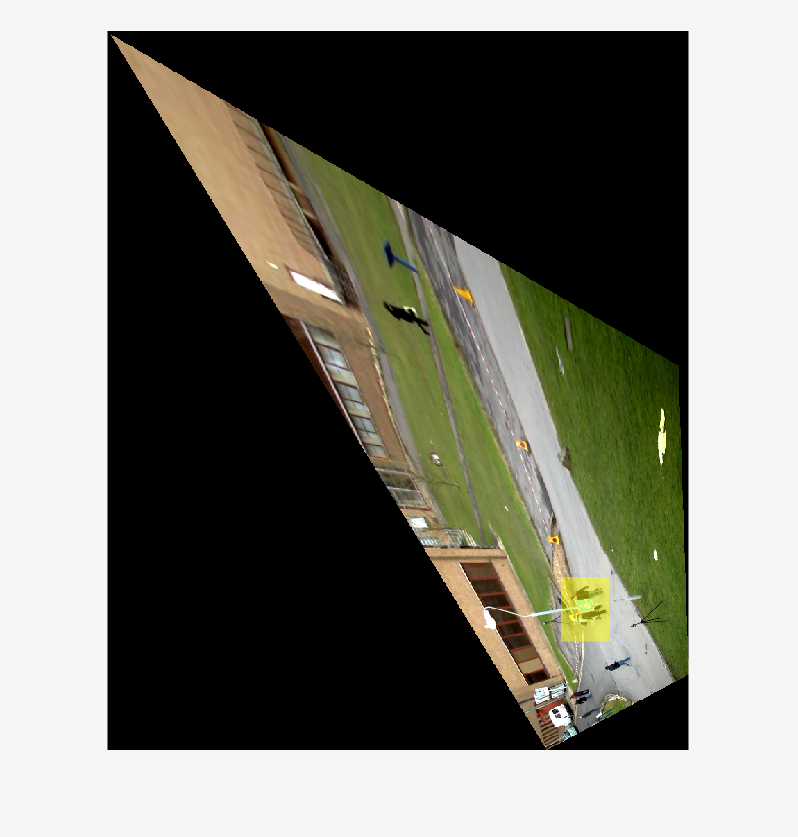

[x, y] = transformPointsForward(T, Porig(:,1), Porig(:, 2));
[xdataI,ydataI] = worldToIntrinsic(RB,x,y);
IBird2 = insertShape(IBird, 'FilledPolygon', reshape([xdataI, ydataI]', 1, []), "Opacity",0.5);
imshow(IBird2)

clear all;close all;